%Mp<20% ts<5seg
%para la 7-64 MP<40% y Ts<=5
clc
clear
close all
s=tf('s');
Gs=(1)/(s*(s+3)*(s+7)) %Ejercicio 4 Ev=25 MP=10%

Gs =
 
           1
  -------------------
  s^3 + 10 s^2 + 21 s
 
Continuous-time transfer function.



%Gs=(s+4)/((s+2)*(s+1))
%Funciones de transferencia taller
%s=tf('s');
%Gs=(s+4)/((s+2)*(s-1)) %Ejercicio 1 EP<10% Mp=10% ts=4.5s
%Gs=(1)/(s*(s+1)*(s^2+10*s+26))%Ejercicio2 15%<Mp>20% Ts=7%
%Gs=(1)/((s^2+4*s+8)*(s+10))%Ejercicio 3 MP<22% Ts<1.6 Kp=15
%Gs=(1)/(s*(s+3)*(s+7)) %Ejercicio 4 Ev=25
Mp=0.10; Ts=20;

isstable(Gs)

ans = logical
   0


Tk=feedback(Gs,1)

Tk =
 
             1
  -----------------------
  s^3 + 10 s^2 + 21 s + 1
 
Continuous-time transfer function.



isstable(Tk)

ans = logical
   1


ProcentajeCriterioTs=0.02;
CriterioRiso=[0.10 0.90];
ParametroSys(Tk,ProcentajeCriterioTs,CriterioRiso) %el sistema es inestable en LO no se analiza mas nada

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -4.87e-02     1.00e+00       4.87e-02         2.05e+01    
 -2.92e+00     1.00e+00       2.92e+00         3.43e-01    
 -7.04e+00     1.00e+00       7.04e+00         1.42e-01    


Resultados =     '
     Ts(2.00)=80.7487
     Tr=45.0786
     Mp=0.0000
     Tp=150.2148
     Tao=17.5541
     ValorF=1.0000
     '


ans = 80.7487

% kp=dcgain(Gs)
% kv=dcgain(Gs*s)
% ka=dcgain(Gs*s^2)
% eep=1/(1+kp)
% eev=1/kv
% eea=1/ka

figure(1)
step(Gs,Tk)
figure(2)
subplot(221),rlocus(Gs)
subplot(223),nyquist(Gs)
subplot(122),margin(Gs)
%% Calcular polos deseados y posicion
clc
close all
Sigma=-log(ProcentajeCriterioTs)/Ts

Sigma = 0.1956

Zeta=-log(Mp)/(sqrt(log(Mp)^2+pi^2))

Zeta = 0.5912

Wn=Sigma/Zeta

Wn = 0.3309

Wd=Wn*sqrt(1-Zeta^2)

Wd = 0.2669

%rlocus(Gs)
%sgrid(Zeta,00

[C]=LeadLagLGR(Gs,Sigma,Wd,0,1,0,3)

s =
 
  s
 
Continuous-time transfer function.



Beta = 21

C =
 
  6.5582 (s+0.01956)
  ------------------
    (s+0.0009314)
 
Continuous-time zero/pole/gain model.



%% 
clc
close all
GsC=C*Gs

GsC =
 
      6.5582 (s+0.01956)
  ---------------------------
  s (s+0.0009314) (s+3) (s+7)
 
Continuous-time zero/pole/gain model.




Tc=feedback(GsC,1); %sistema controlado
Tk=feedback(Gs,1);
Su=feedback(C,Gs); %señal de control
ParametroSys(Tc,ProcentajeCriterioTs,CriterioRiso)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -2.09e-02     1.00e+00       2.09e-02         4.79e+01    
 -3.53e-01     1.00e+00       3.53e-01         2.83e+00    
 -2.41e+00     1.00e+00       2.41e+00         4.15e-01    
 -7.22e+00     1.00e+00       7.22e+00         1.39e-01    


Resultados =     '
     Ts(2.00)=NaN
     Tr=5.1686
     Mp=4.7648
     Tp=17.2603
     Tao=NaN
     ValorF=1.0000
     '


ans = NaN

ErroEpEvEa(GsC)

ans = 0

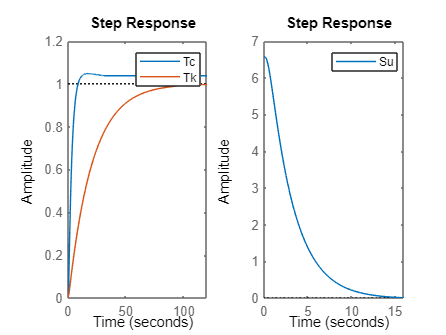

figure(2)
subplot(121),step(Tc,Tk),legend
subplot(122),step(Su),legend

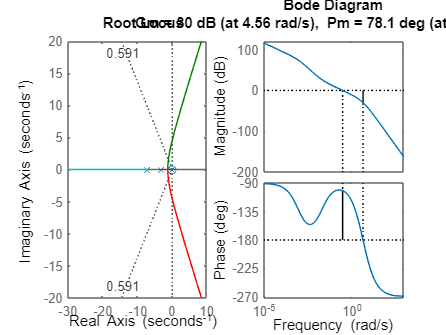

figure(3)
subplot(121),rlocus(GsC),sgrid(Zeta,0)
subplot(122),margin(GsC)

Tkp=dcgain(Tc)

Tkp = 1.0000

Tkv=dcgain(Tc*s)

Tkv = 0

Tka=dcgain(Tc*s^2)

Tka = 0

Teep=1/(1+Tkp)

Teep = 0.5000

Teev=1/Tkv

Teev = Inf

Teea=1/Tka

Teea = Inf